# **demo06 of Im2mesh package**

demo06 - Thresholds in polyline smoothing

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

## Circle

Let's start demo. Import image Circle.tif.

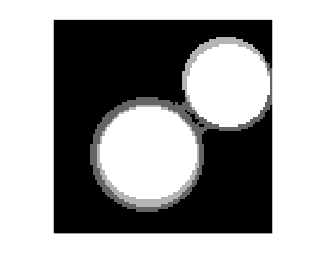

im = imread('Circle.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Zoom in

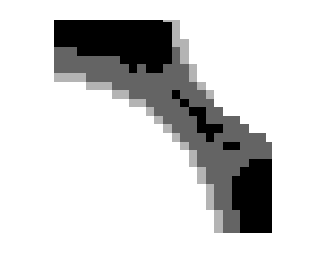

imshow( im,'InitialMagnification','fit' );
xlim([40.8 66.2])
ylim([29.3 54.2])

## When thresholds are zeros

opt = [];
% thresholds for polyline smoothing
opt.threshold_num_turning = 0;
opt.threshold_num_vert_Smo = 0;

opt.tolerance = 0.01;  % do not simplify polyline

[vert,tria,tnum] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          6                683               1094
         10                715               1737
         20                723               2772
         20                723               2772


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10                945               1094
         10                945               1094
         20               1011               9263
         25               1016               9544


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
     

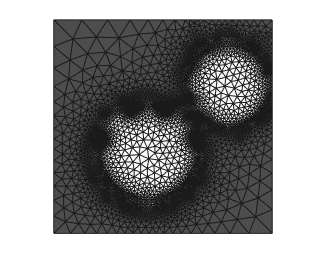

plotMeshes(vert,tria,tnum)

Zoom in

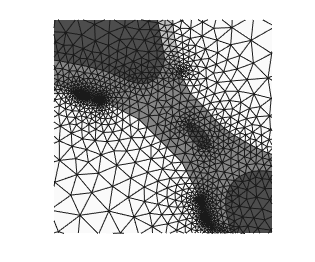

plotMeshes(vert,tria,tnum)
xlim([41.6 67.0])
ylim([36.2 61.1])

We saw some polygons were disappeared when compared to the input image. This disappearing issue is caused by polyline over-smoothing. 

We can set thresholds for polyline smoothing to avoid this issue.

## Set thresholds for polyline smoothing

opt = [];
% thresholds for polyline smoothing
opt.threshold_num_turning = 10;
opt.threshold_num_vert_Smo = 20;

opt.tolerance = 0.01;  % do not simplify polyline

[vert,tria,tnum] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          6                678               1186
         10                708               1596
         20                713               2369
         20                713               2369


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10                891               1186
         10                891               1186
         20                919               7026
         25                922               7161


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
     

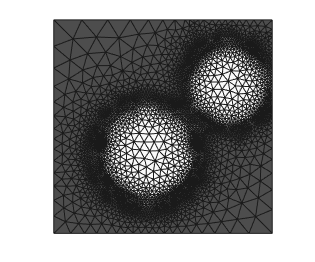

plotMeshes(vert,tria,tnum)

Zoom in

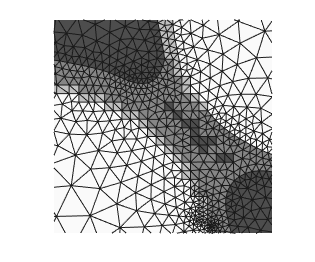

plotMeshes(vert,tria,tnum)
xlim([41.6 67.0])
ylim([36.2 61.1])

The new boundaries are better. 

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo